load hall.mat;
ori_img = hall_gray;
[H,W] = size(ori_img);
info_size = H*W;

info_img = ori_img;
% 将信息转化为二进制码流
info = randi([0,1],[1,info_size]);
% 隐藏信息
for i = 1:1:H
    for j = 1:1:W
        if info(168*i+j-168)==1 && mod(ori_img(i,j),2)==0
            info_img(i,j) = info_img(i,j)+1;
        elseif info(168*i+j-168)==0 && mod(ori_img(i,j),2)==1
            info_img(i,j) = info_img(i,j)-1;
        end
    end
end

% 压缩后再解压
[DC_code,AC_code,H,W] = compress(info_img)

DC_code =      1     1     1     0     1     1     1     0     0     1     1     0     0     1     1     0     1     1     1     0     1     0     1     0     1     0     1     1     1     0     1     0     0     1     0     1     1     0     0     1     0     0     0     0     0     0     0     0     0     0


AC_code =      0     0     1     0     1     1     0     0     0     1     1     1     0     0     0     1     1     0     1     1     0     1     0     1     0     0     1     1     1     0     1     0     1     1     1     1     1     0     0     1     1     0     0     0     0     0     0     1     1     0


H = 120

W = 168

com_img = decompress(DC_code,AC_code,H,W);
com_info = zeros(1,info_size);
% 提取隐藏信息
for i = 1:1:H
    for j = 1:1:W
        com_info(168*i+j-168) = mod(com_img(i,j),2);
    end
end

% 与原信息比较
count = 0;
for i = 1:1:info_size
    if info(i)==com_info(i)
        count = count +1;
    end
end
acc = count/info_size

acc = 0.4957

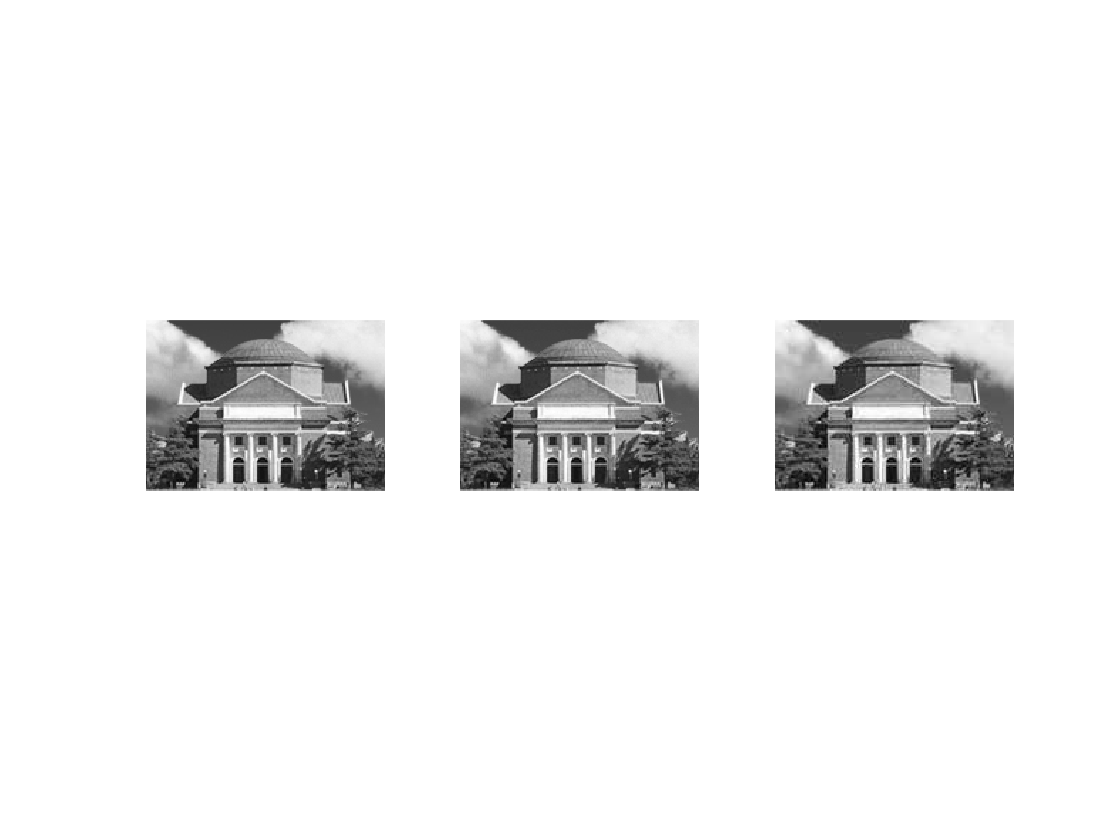

subplot(1,3,1);
imshow(ori_img);
subplot(1,3,2);
imshow(info_img);
subplot(1,3,3);
imshow(com_img);